# DeconvolutionLab2 pruebas

javaaddpath([matlabroot filesep 'java' filesep 'DeconvolutionLab_2.jar']);

________________________________________________________________________________________________________

## Cube of Spherical Beads

img = tiffreadVolume('cubeConvolved.tif');
img_b = tiffreadVolume('PSF.tif');

result = DL2.RL(img, img_b, 30,'-out stack');

Log   	 322,79 us 	  397,7Mb  	 DeconvolutionLab2 2.1.2 (27.06.2018) on Matlab
Log   	 764,88 us 	  462,5Mb  	 AcademicFFT Added
Log   	 2856,04 us 	  462,5Mb  	 JTransforms not found
Log   	 4,16 ms 	  463,4Mb  	 FFTW Widsom not found in : /Applications/MATLAB_R2024a.app/java/FFTW/
Log   	 4,61 ms 	  463,4Mb  	 FFTW Widsom not found in : /Applications/MATLAB_R2024a.app/java/
Log   	 4,68 ms 	  463,4Mb  	 FFTW Widsom not found in : /Users/yi/FFTW/
Log   	 4,72 ms 	  463,4Mb  	 FFTW Widsom not found in : /Users/yi/
Log   	 4,77 ms 	  463,4Mb  	 FFTW not found
Log   	 6,38 us 	  477,0Mb  	 Create Live Real Signal 


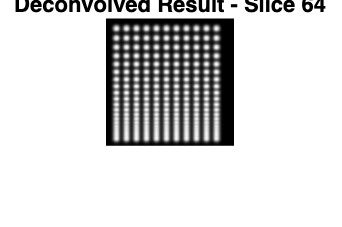

figure;
imshow(result(:,:,64), []);
title('Deconvolved Result - Slice 64');

________________________________________________________________________________________________________

## C. Elegans Embryo